# Calibration Step 3 - Part 1: Data Processing

This script performs post-processing of the raw initial condition response data

Input: Data read-in from datafiles/step3/initialconditiondata_X.dat where X is the trial index.

Output: Experimental estimates of the natural frequencies and damping ratios for the first 2 wing bending modes. 

## Read in the data

clear all;
addpath('utilityfunctions')

% 5 data files corresponding to 5 repeated trials of the experiment
Datafiles = {};
for i = 1:5
    Datafiles{i} = sprintf('./datafiles/step3/initialconditiondata_%d.DAT',i);
end

% Read data from initial condition test
time = {};
spanwise = {};
chordwise = {};
for i = 1:length(Datafiles)
    flname = Datafiles{i}    
    temp = load(flname);
    
    % Decimate - downsample data from 100kHz to 2kHz for high frequency noise reduction + faster processing
    df = 50;
    time{i} = decimate(temp(:,1),df);
    SW{i} = decimate(temp(:,2),df); % strain data from the sensor oriented spanwise
    CW{i} = decimate(temp(:,3),df); % strain data from the sensor oriented chordwise (not used in this work)
    
    %% crop data to start at first peak, detrend to remove any drift
    mask = time{i}>0.00548;
    time{i} = time{i}(mask);
    spanwise{i} = detrend(SW{i}(mask));
    chordwise{i} = detrend(CW{i}(mask)); 
    
    Ts(i) = time{i}(101)-time{i}(100);    % data time period
    fs(i) = 1/Ts(i);       % data sampling frequency
end

flname = './datafiles/step3/initialconditiondata_1.DAT'

flname = './datafiles/step3/initialconditiondata_2.DAT'

flname = './datafiles/step3/initialconditiondata_3.DAT'

flname = './datafiles/step3/initialconditiondata_4.DAT'

flname = './datafiles/step3/initialconditiondata_5.DAT'

## Plot the raw data

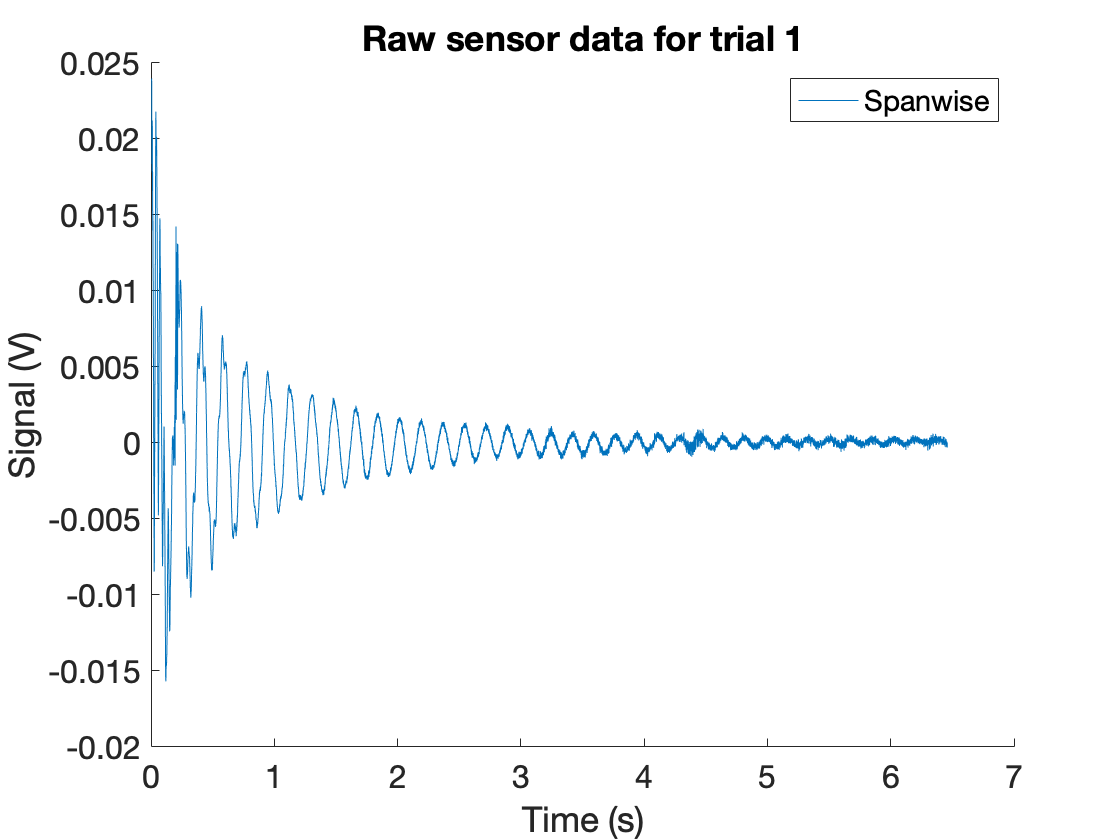

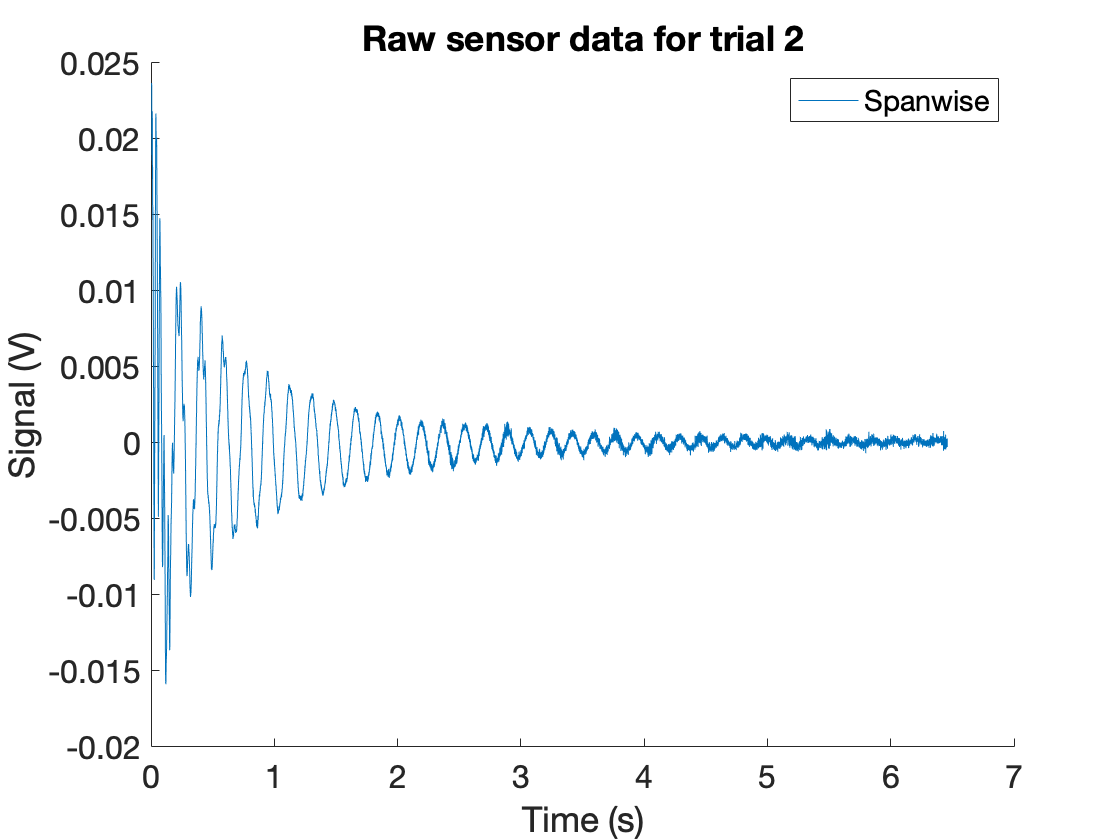

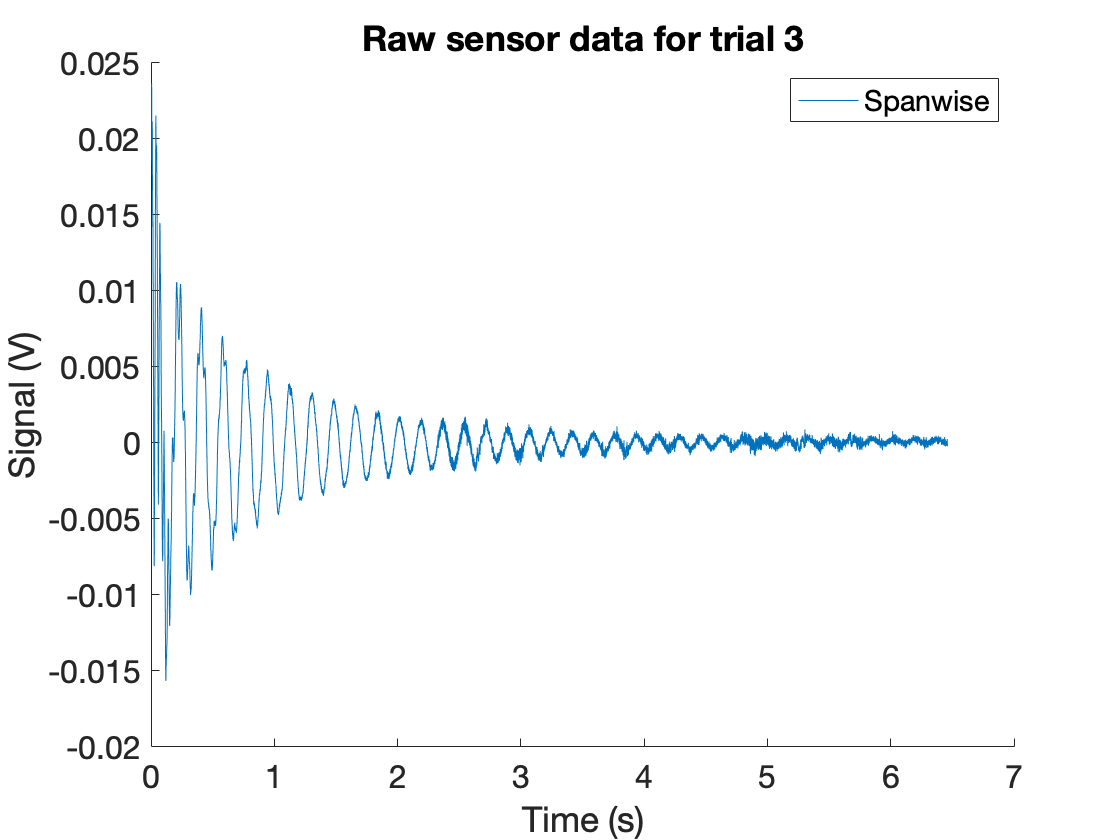

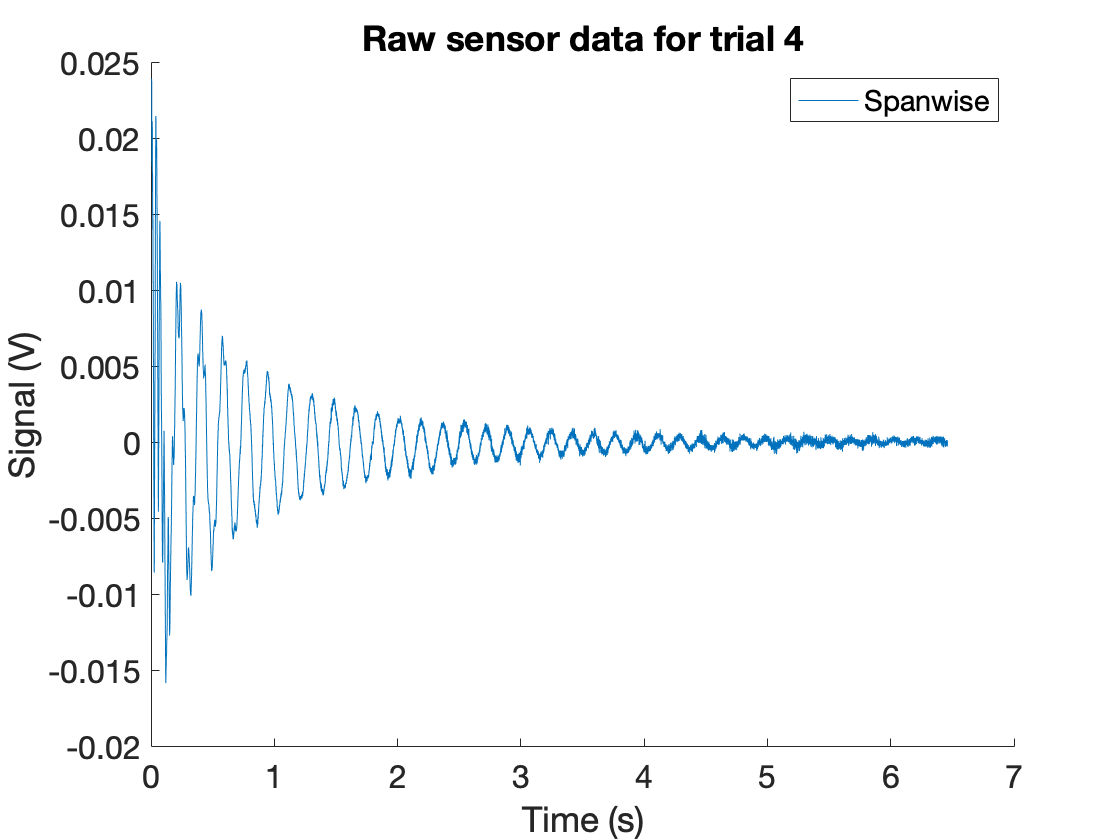

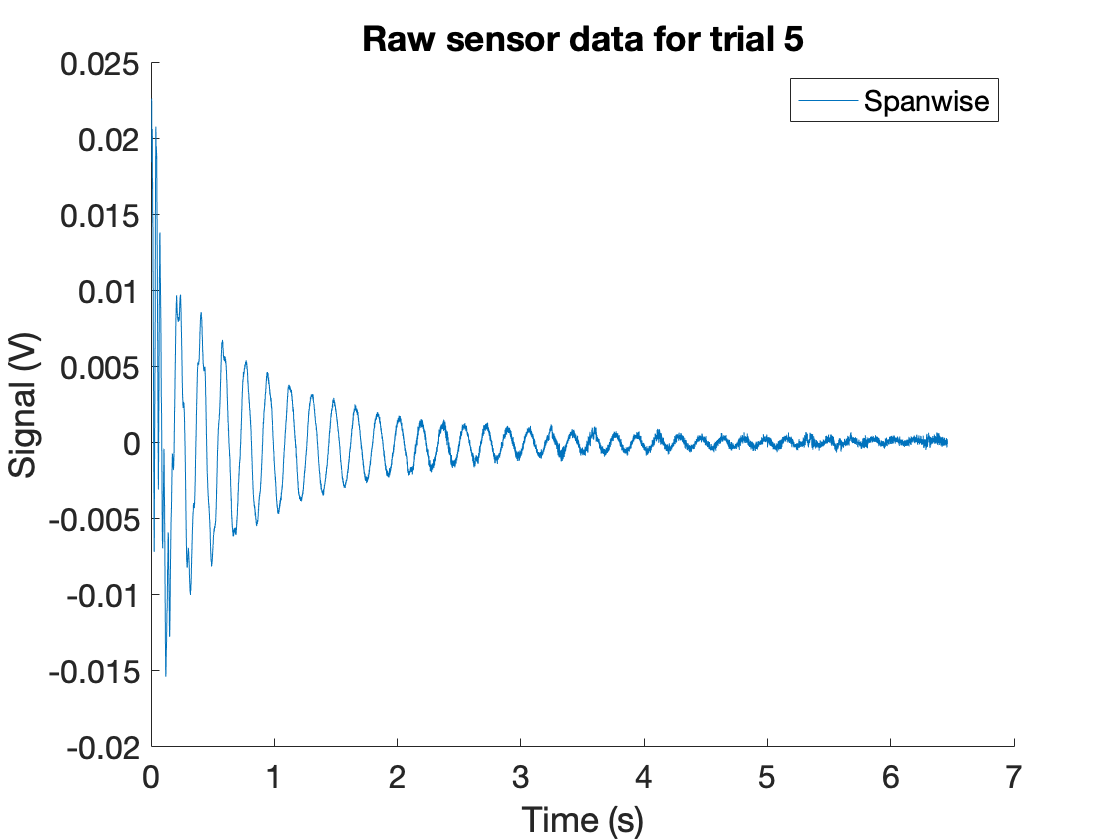

figure
for i = 1:length(Datafiles)
    figure;
    hold on;
    
    plot(time{i},spanwise{i});
    
    title(sprintf('Raw sensor data for trial %d', i))
    xlabel('Time (s)')
    ylabel('Signal (V)')
    legend('Spanwise') 
    ax = gca;
    set(ax, 'FontSize', 16);
end

## Plot Power spectrum of each signal

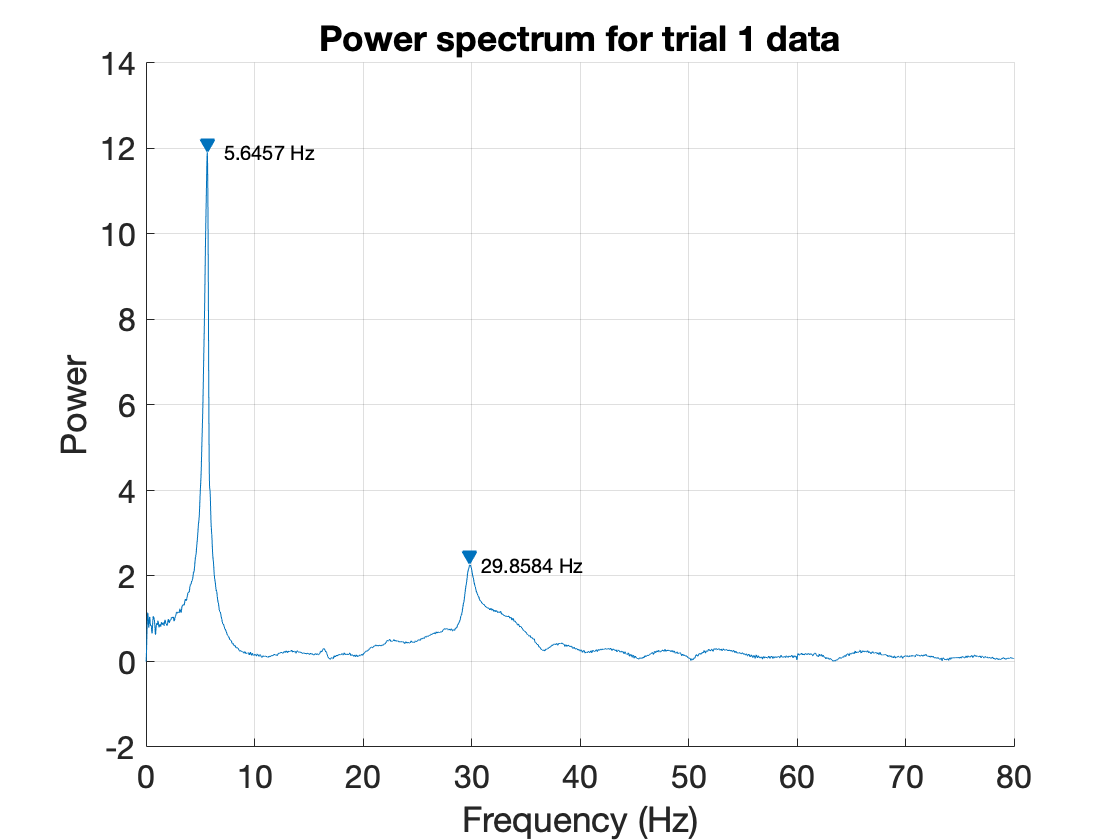

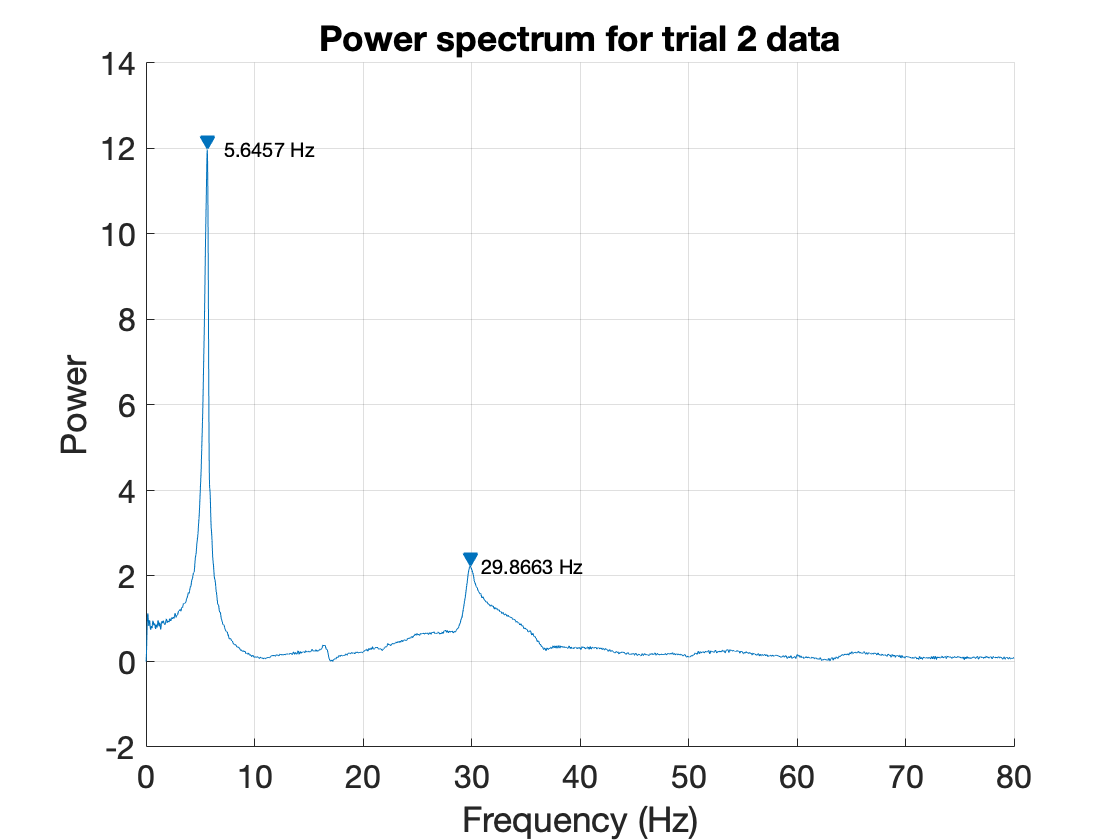

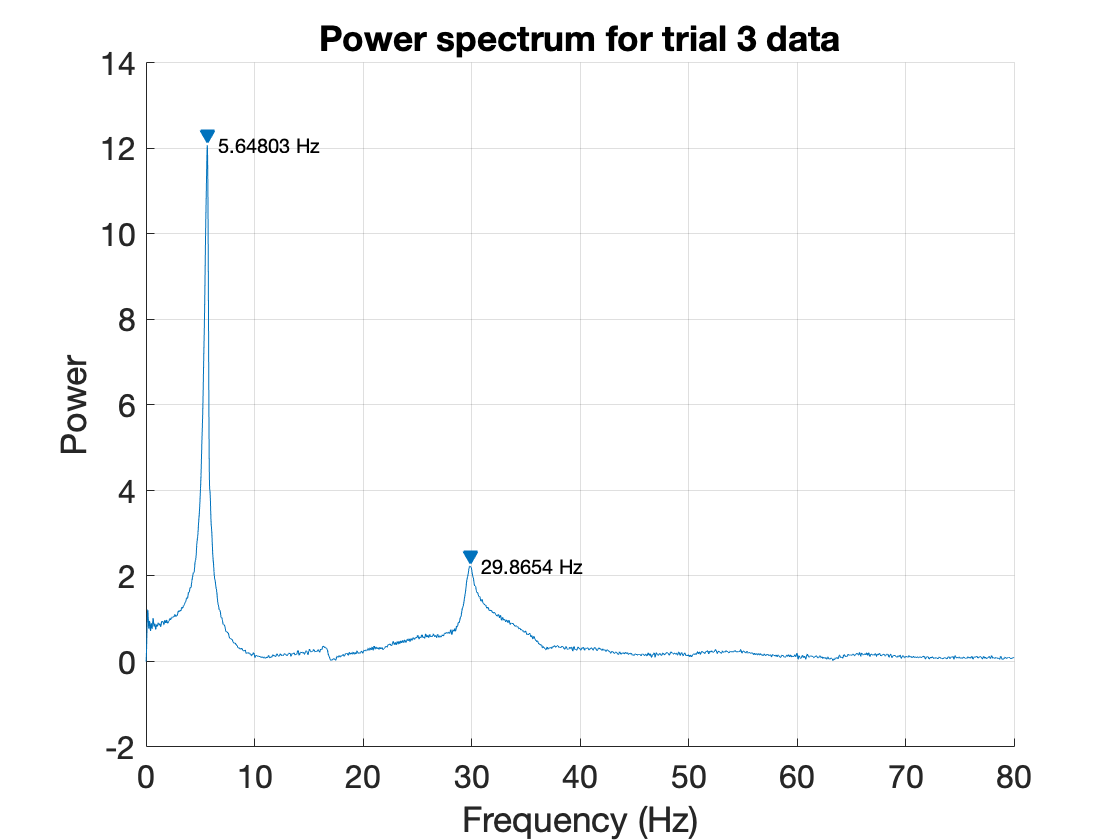

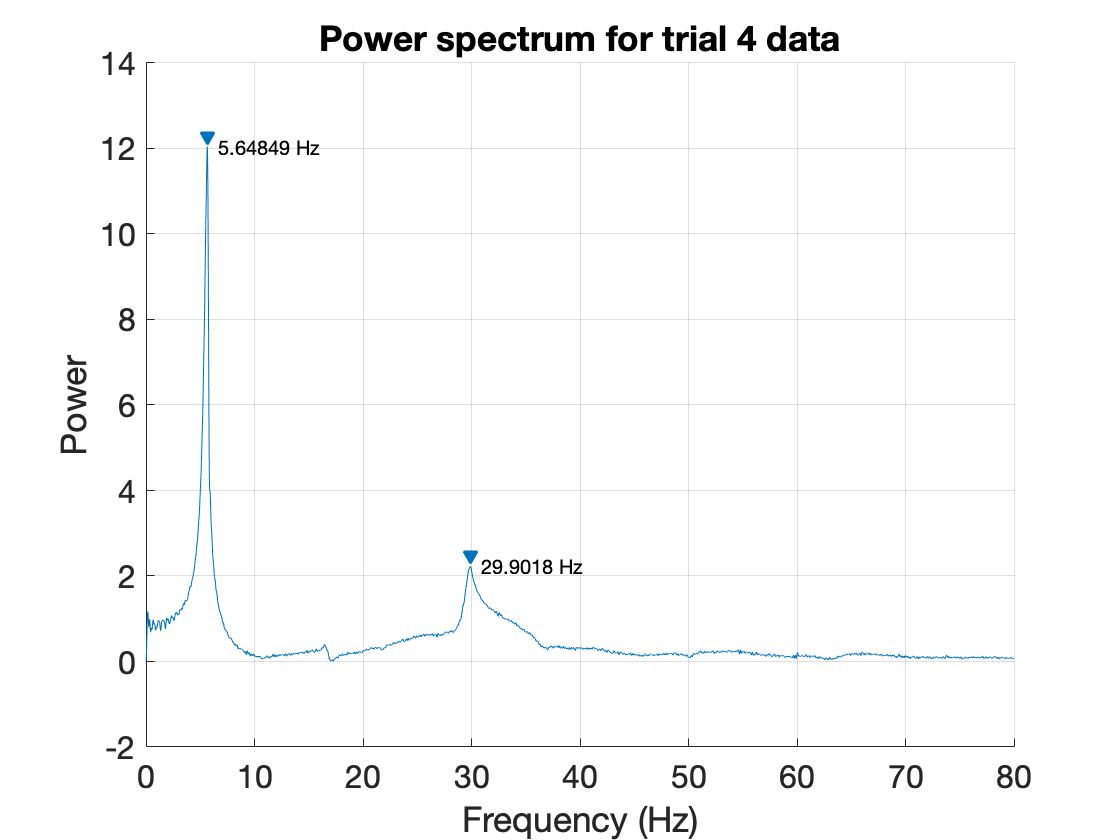

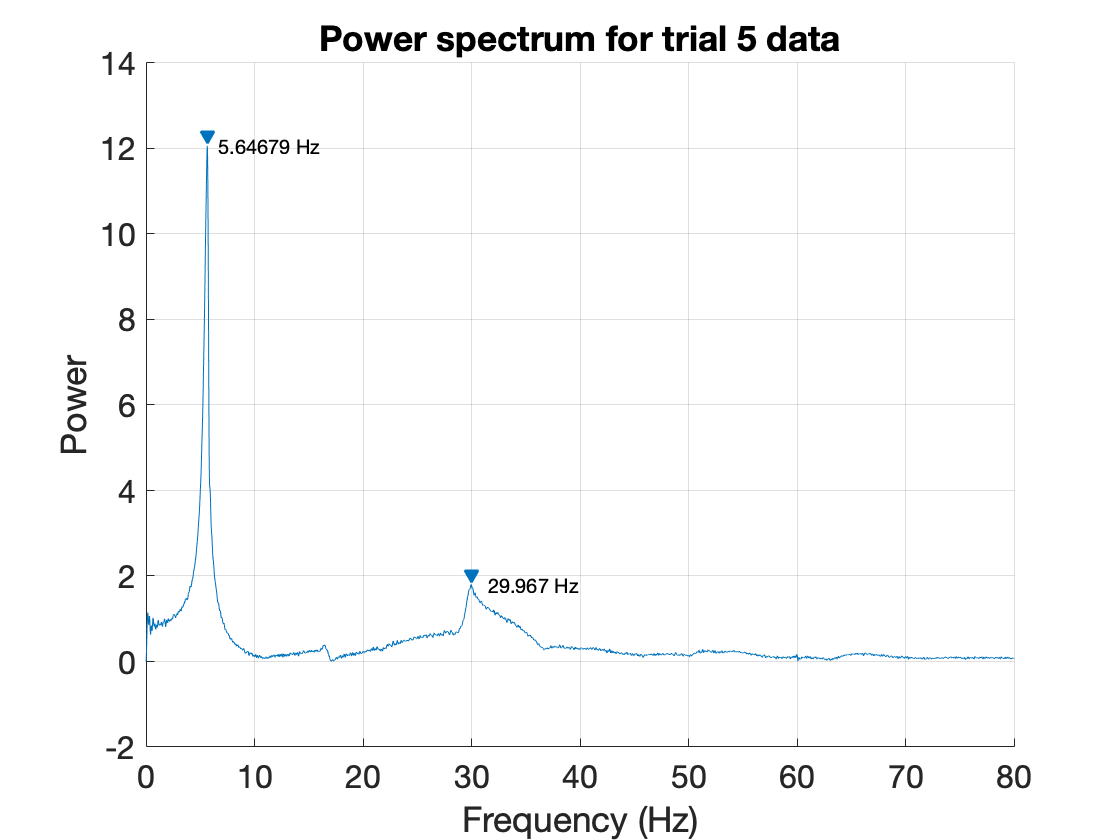

pks = {};
frequency = {};
for i = 1:length(Datafiles)
    figure;
    hold on;
    n = 1000*length(spanwise{i}); % number of samples
    y = fft(spanwise{i},n);   
    f = (0:n-1)*(fs(i)/n);     % frequency range
    power = abs(y).^2/n;    % power of the signal
    
    % use findpeaks to extract modal frequencies
    [pks{i},frequency{i}] = findpeaks(abs(y(f<80)),f(f<80),'NPeaks',2,'minpeakprominence',0.05,'SortStr','descend'); % extract peaks    
    findpeaks(abs(y(f<80)),f(f<80),'NPeaks',2,'minpeakprominence',0.05,'SortStr','descend') % call again to plot...
    text(frequency{i}+1,pks{i},[num2str( frequency{i}' ),repmat(' Hz', numel(frequency{i}),1)])
    m(i) = length(pks{i}); % number of modes identified for trial i
    
    title(sprintf('Power spectrum for trial %d data', i))
    xlabel('Frequency (Hz)')
    ylabel('Power')    
    xlim([0 80])
    ax = gca;
    set(ax, 'FontSize', 16);
end

## Filter signal to extract modes 1 and 2

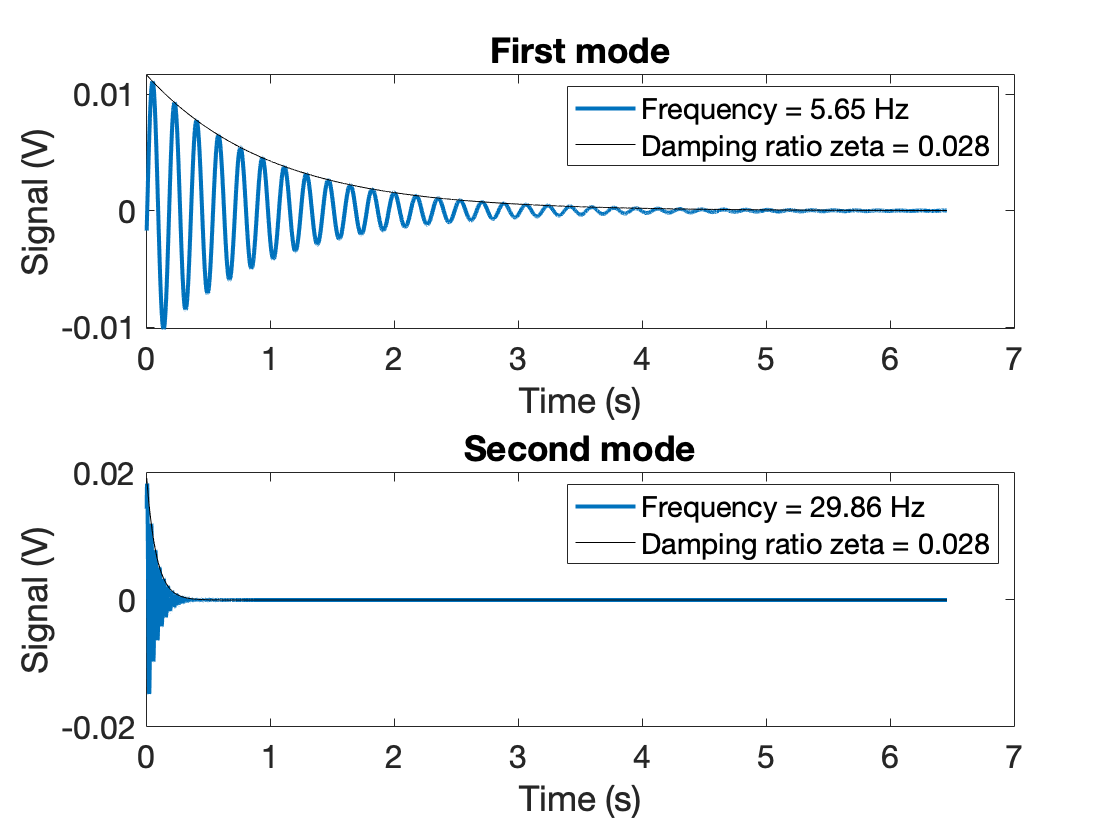

for i = 1:1%length(Datafiles)
    % fit a sum of damped cosine at each of the extracted frequencies to the measured signal
    [exponential_ic{i}, exponential_decay_rate{i}, omega{i}, zeta{i}, spanwise_components{i}] = fit_damped_cosine(time{i},spanwise{i},frequency{i},0);
    
%     % Plot raw data 
    figure;
%     subplot(3,1,1)
%     plot(time{i},spanwise{i},'DisplayName','Raw Data','LineWidth',0.1);
%     title('Raw data')
    
    % Plot mode 1
    subplot(2,1,1)
    plot(time{i},spanwise_components{i}(:,1),'Linewidth',2,'DisplayName',sprintf('Frequency = %.2f Hz',frequency{i}(1)));
    hold on;
    plot(time{i},abs(exponential_ic{i}(1)*exp(-1*exponential_decay_rate{i}(1)*time{i})),'k','DisplayName',sprintf('Damping ratio zeta = %.3f',zeta{i}(1)));
    title('First mode')
    
    % Plot mode 2
    subplot(2,1,2)
    plot(time{i},spanwise_components{i}(:,2),'Linewidth',2,'DisplayName',sprintf('Frequency = %.2f Hz',frequency{i}(2)));
    hold on;
    plot(time{i},abs(exponential_ic{i}(2)*exp(-1*exponential_decay_rate{i}(2)*time{i})),'k','DisplayName',sprintf('Damping ratio zeta = %.3f',zeta{i}(1)));
    title('Second mode')
    
    % formatting
    for j = 1:m(i)
        subplot(2,1,j)
        ax = gca;
        set(ax, 'FontSize', 16);
        xlabel('Time (s)');
        ylabel('Signal (V)');
        legend;
    end    
end

## Plot recreated signals and compute RMS errors

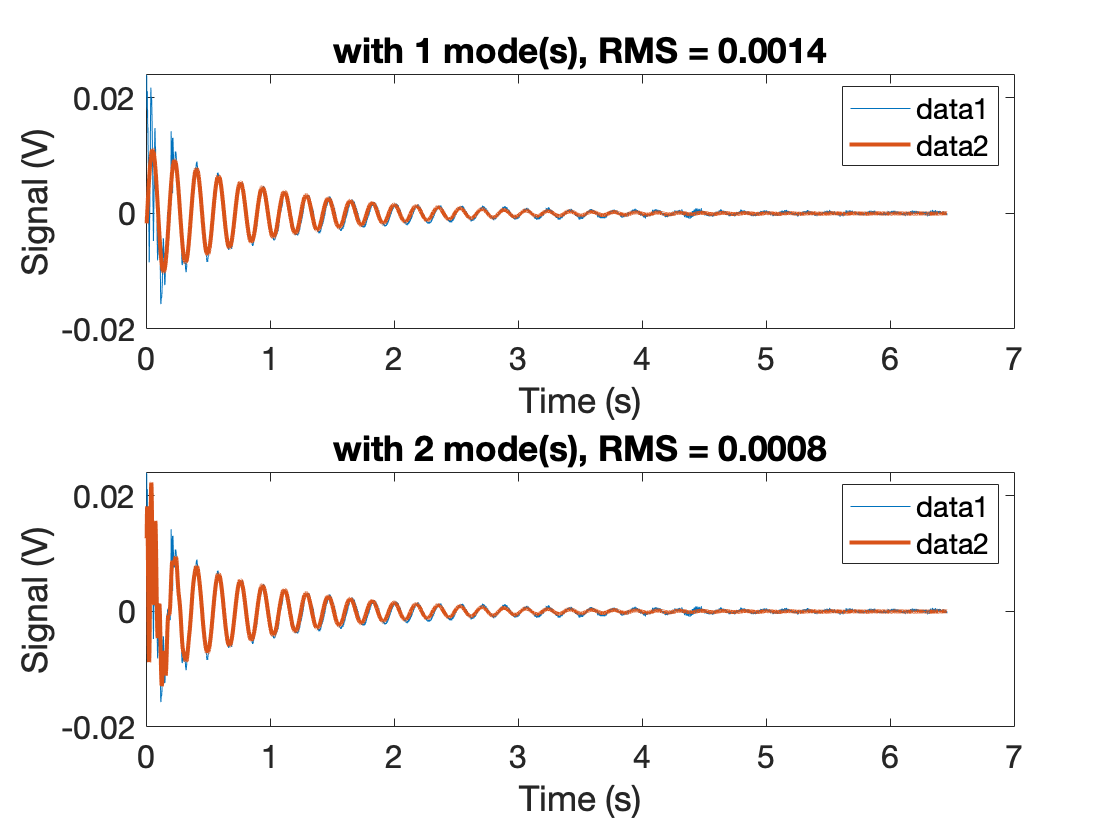

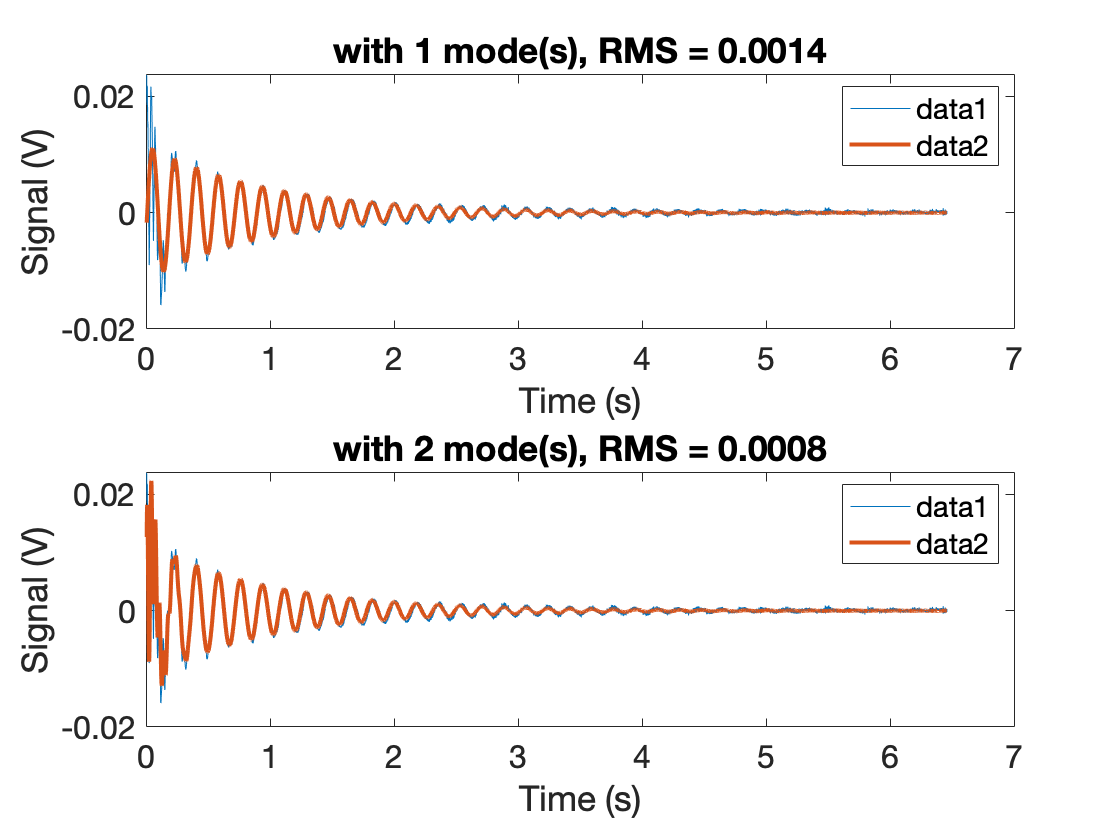

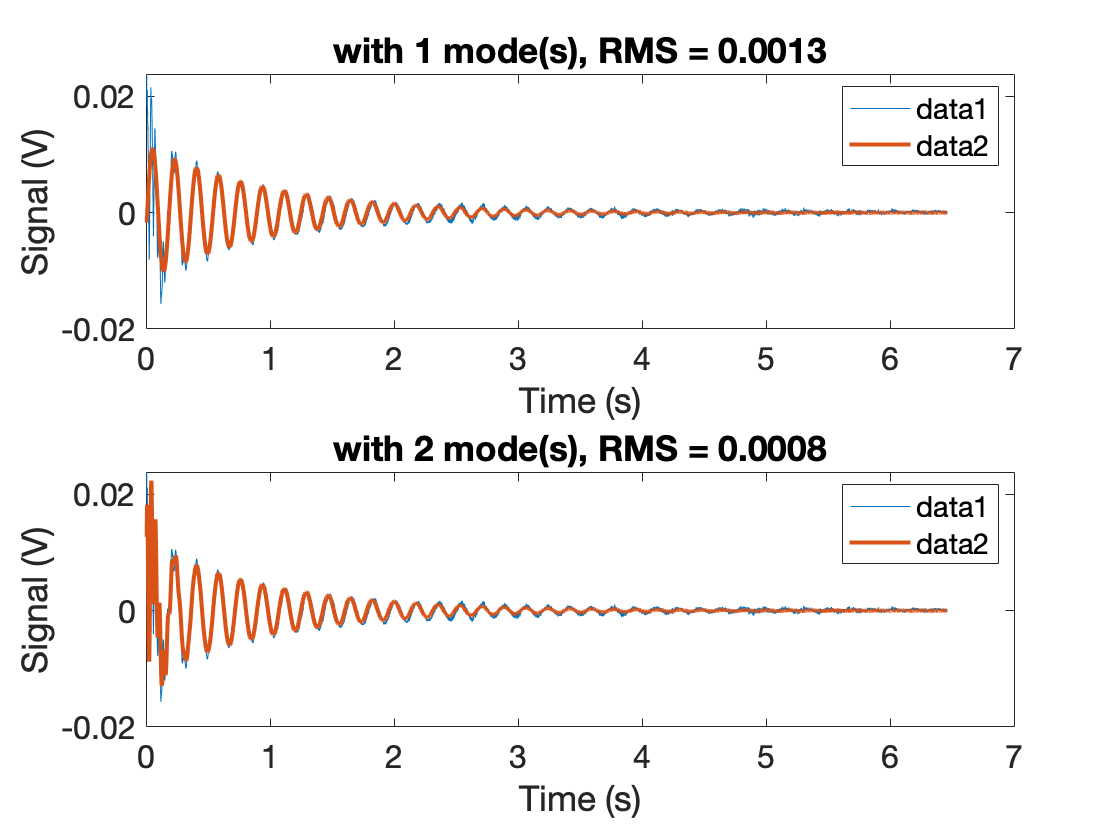

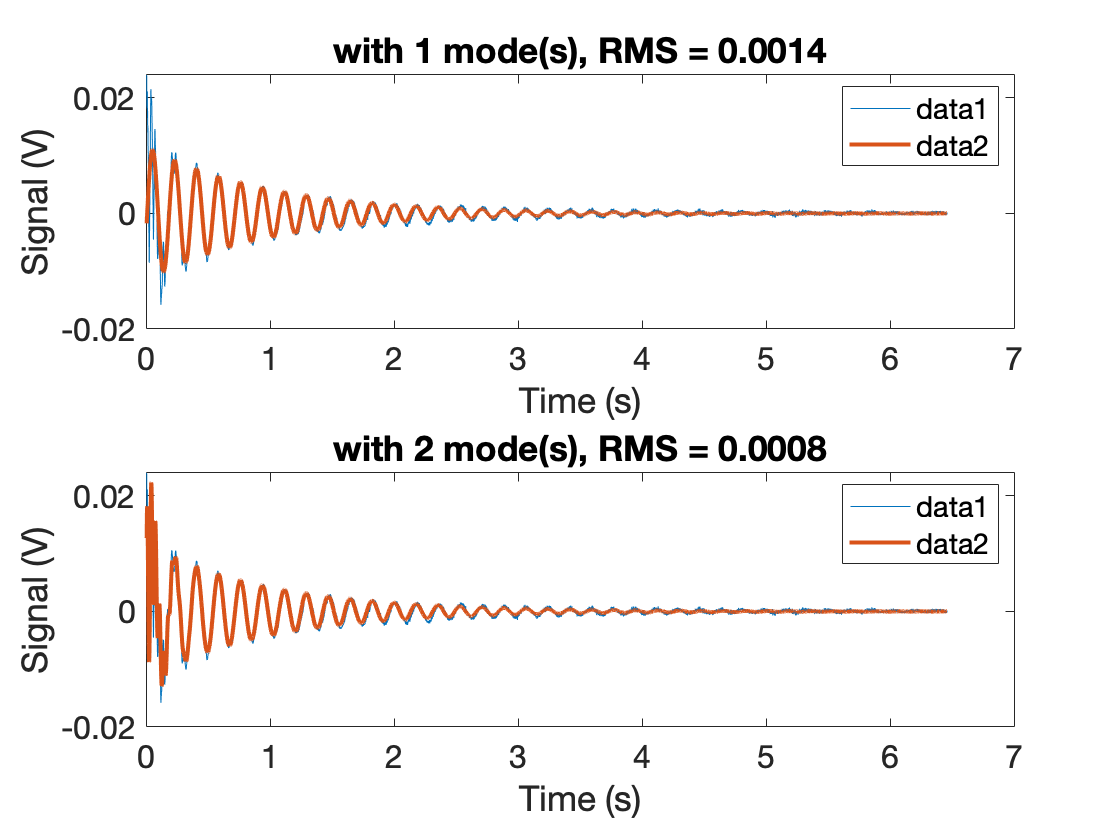

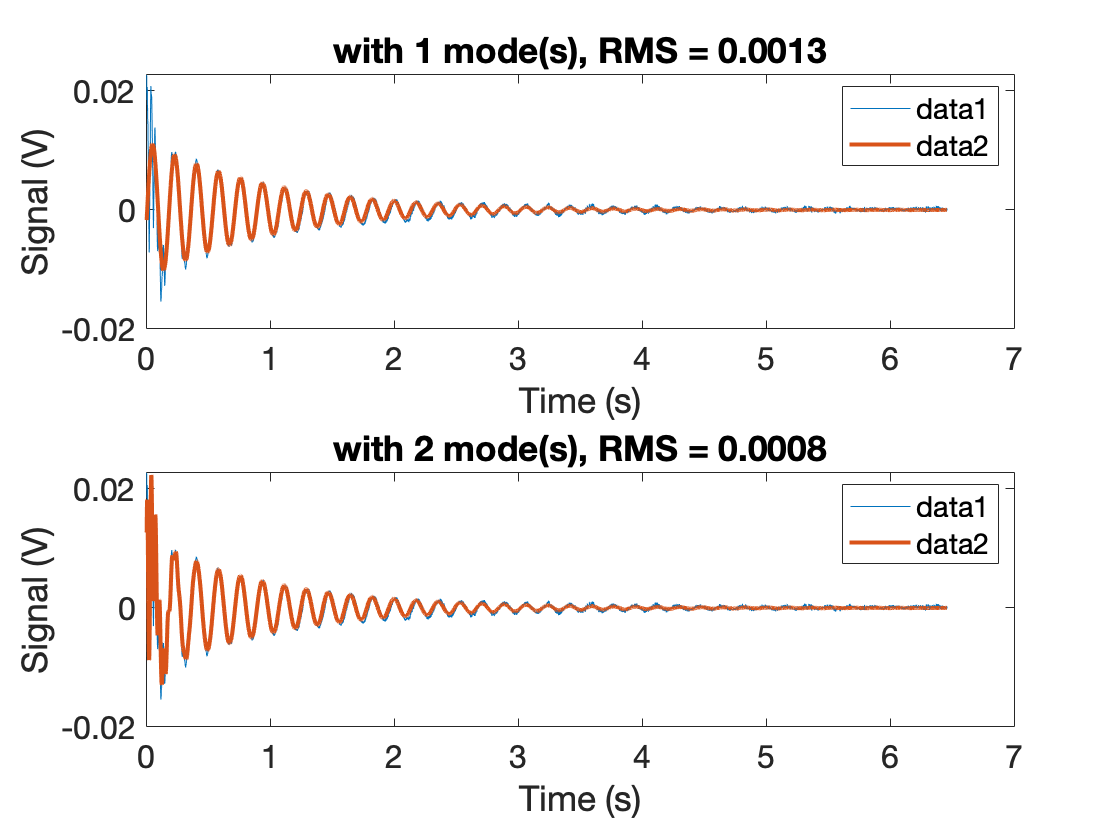

RMS = {};
for i = 1:length(Datafiles)
    figure;
    for j = 1:m(i)
        subplot(m(i),1,j)
        % plot raw data
        plot(time{i},spanwise{i});
        hold on;
        % plot recreated signal with j modes
        plot(time{i},sum(spanwise_components{1}(:,1:j),2),'linewidth',2);
        %compute RMS error
        RMS{i}(j) = sqrt(mean((spanwise{i} - sum(spanwise_components{1}(:,1:j),2)).^2));
        
        
        % formatting
        ax = gca;
        title(sprintf('with %d mode(s), RMS = %.4f',j,RMS{i}(j)))
        set(ax, 'FontSize', 16);
        xlabel('Time (s)');
        ylabel('Signal (V)');
        legend;   
    end
end

## Convert damped natural frequencies into undamped natural frequencies using damping ratios

damped_frequencies_mode1 = cellfun(@(v)v(1),frequency);
damped_frequencies_mode2 = cellfun(@(v)v(2),frequency);

zeta_mode1 = cellfun(@(v)v(1),zeta);
zeta_mode2 = cellfun(@(v)v(2),zeta);

undamped_frequencies_mode1 = damped_frequencies_mode1./sqrt(1-zeta_mode1.^2);
undamped_frequencies_mode2 = damped_frequencies_mode2./sqrt(1-zeta_mode2.^2);

fprintf('Mode 1: f = %.2f, zeta = %.4f', mean(undamped_frequencies_mode1), mean(zeta_mode1));

Mode 1: f = 5.65, zeta = 0.0284

fprintf('Mode 2: f = %.2f, zeta = %.4f', mean(undamped_frequencies_mode2), mean(zeta_mode2));

Mode 2: f = 29.96, zeta = 0.0675